作业一

`1、用程序实现同时对比度实验`

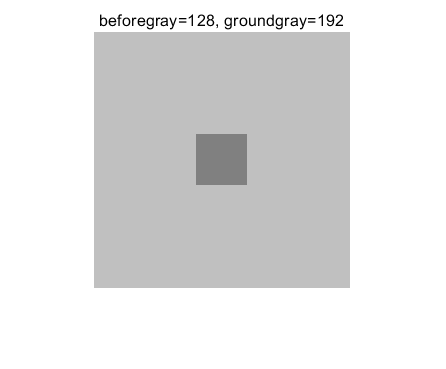

clc;clear;
m=256;n=256;
ground_gray1=128+64;
X = ones(m,n)*ground_gray1;
before_gray=128;
step = 50;
m0 = 0.5*(m-step);n0=0.5*(n-step);%计算m0与n0
X(m0:m0+step,n0:n0+step)=before_gray;
figure(1);
imshow(uint8(X));
title('beforegray=128, groundgray=192');

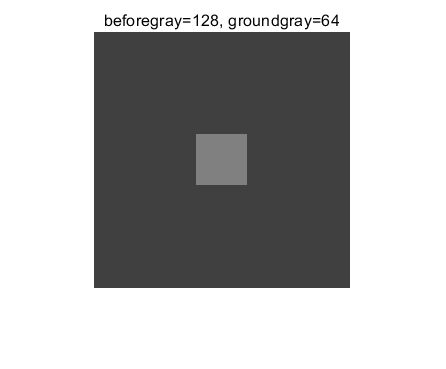

ground_gray2=64;
X = ones(m,n)*ground_gray2;
X(m0:m0+step,n0:n0+step)=before_gray;
figure(2);
imshow(uint8(X));
title('beforegray=128, groundgray=64');

`实验结论：    `

`由实验结果可以看出，在相同灰度值的前景下，由于背景亮度不同`,`人眼所感受到的 主观亮度不同，这种由于亮度差别引起的主观差别称为同时对比度，说明人眼感受到的亮度并不是强度的简单函数。`

`2、 用程序实验空间分辨率变化效果`

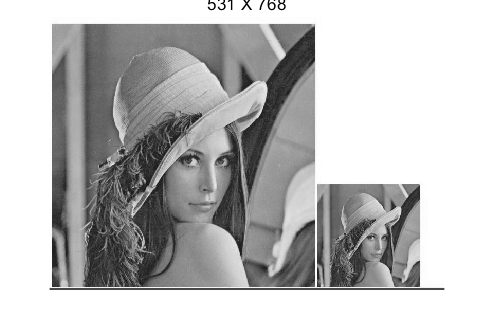

clc;clear;
img=imread('hwk1.jpg');
%转为灰度图像
img_gray=rgb2gray(img);
[m,n]=size(img_gray);
figure(1);
imshow(uint8(img_gray));
title('531 X 768');
img_div_4=img_gray(1:4:m,1:4:n);
figure(2);
imshow(uint8(img_div_4));

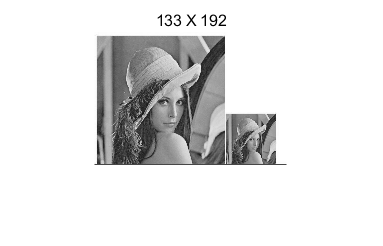

title('133 X 192');
img_div_8=img_gray(1:8:m,1:8:n);
figure(3);
imshow(uint8(img_div_8));

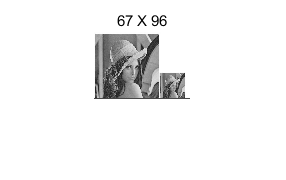

title('67 X 96');

实验结论：

`从上述结果可知，三张图片的图片大小分别为 `531*768,133*192,67*96`，其空间分辨 `

`率逐渐降低，从实际图像来看其锯齿状效应也越来越明显，图片中的边界越来越模 `

`糊。这也说明了人眼对失真的容忍是有界限的。`

`3、用程序实验幅度分辨率变化效果`

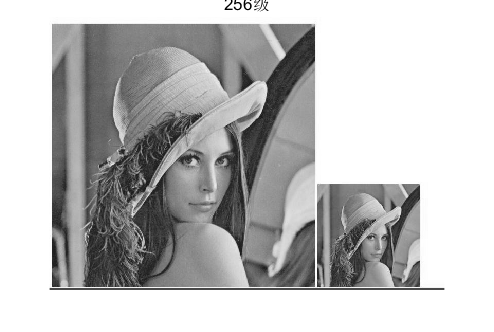

clc;clear;
img=imread('hwk1.jpg');
%转为灰度图像
img_gray=rgb2gray(img);
[m,n]=size(img_gray);
%利用广播机制
img_div16=16*ceil(img_gray/16);
img_div64=64*ceil(img_gray/64);
figure(1);
imshow(uint8(img_gray));
title('256级');

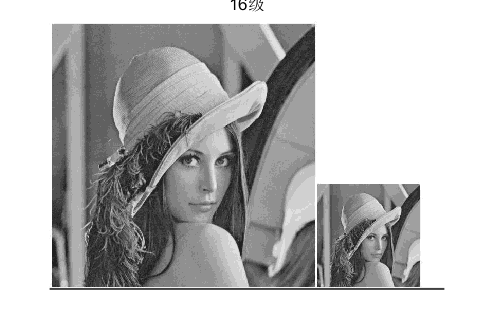

figure(2);
imshow(uint8(img_div16));
title('16级');

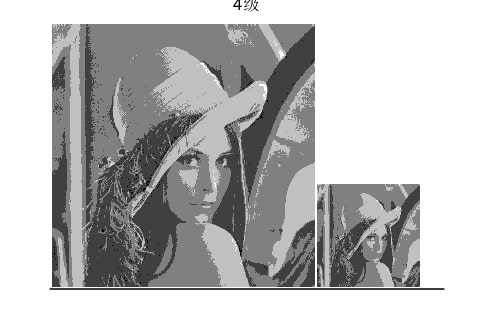

figure(3);
imshow(uint8(img_div64));
title('4级');

实验结论：

`从上述结果可知，三张图片的量化级数分别为 `256`，`16`，`4`，其幅度分辨率逐渐降低， 从实际图像来看其颜色变化也越来越不明显。对一张图片用越高的bit进行量化，其图像的变化就越丰富。`